Parameter values used in this code are directly obtained from the code for the a-z implementation of the bandpass filter. 

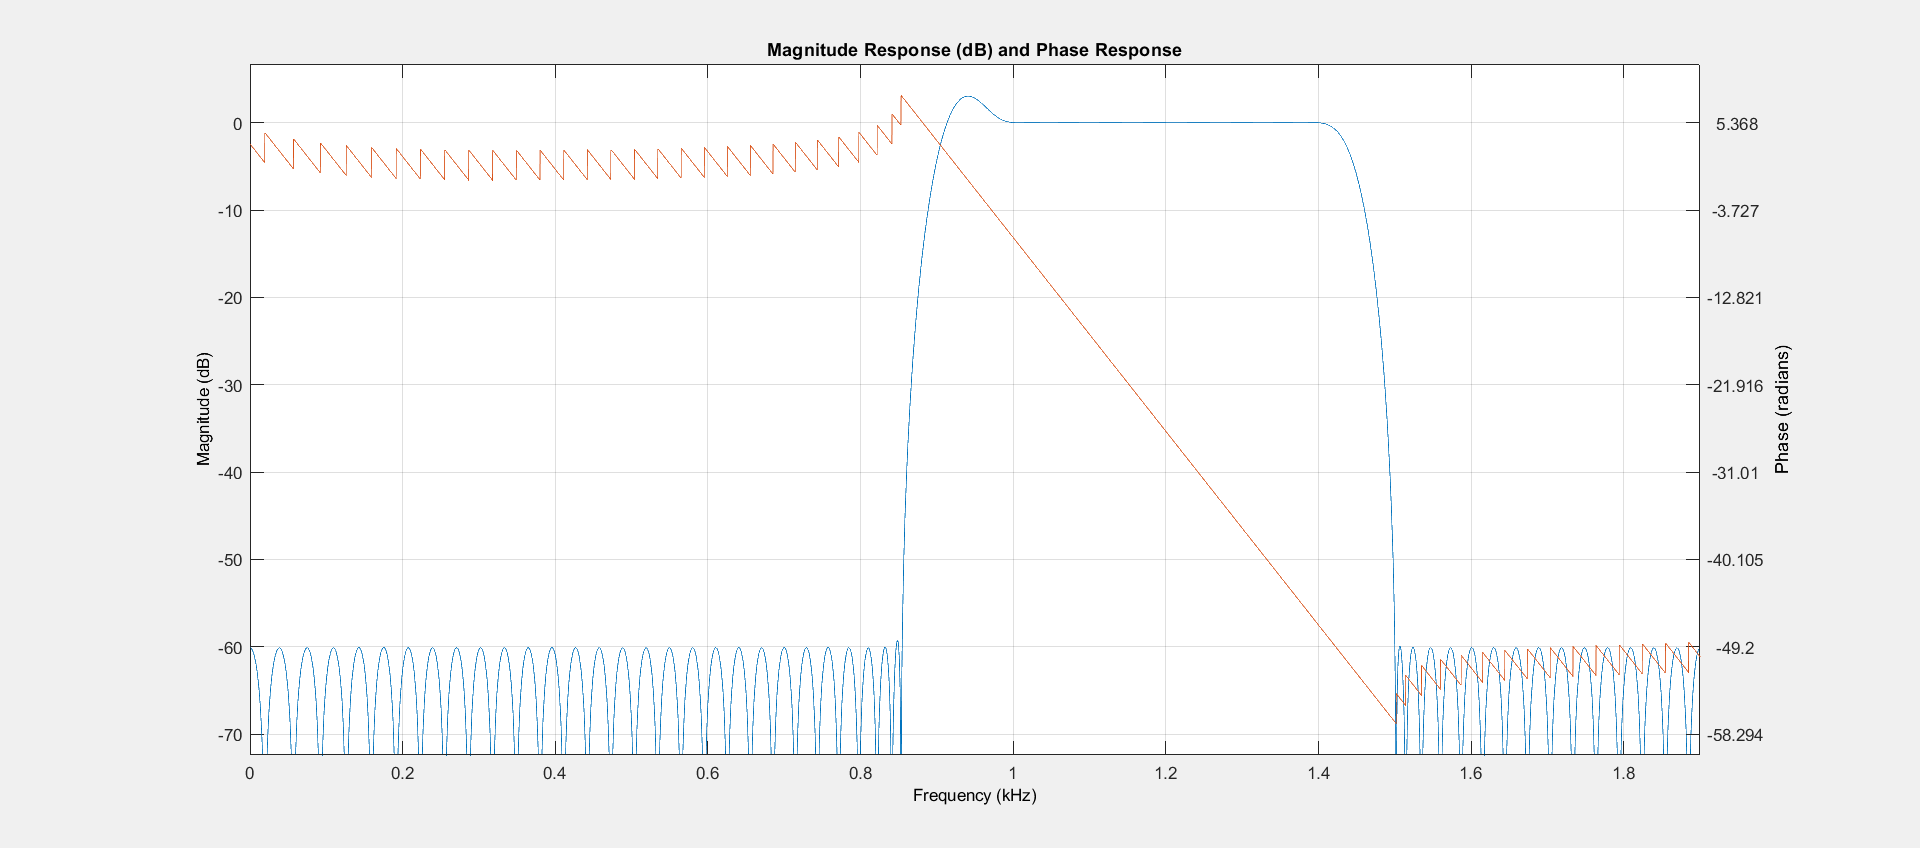

clc; clear; close all;

%Maximum passband ripple in dB
Ap = 0.07;
%Minimum stopband attenuation in dB
Aa = 54;
%Lower passband edge in rad/s
Omega_p1 = 1000;
%Upper passband edge in rad/s
Omega_p2 = 1400;
%Lower stopband edge in rad/s
Omega_a1 = 850;
%Upper stopband edge in rad/s
Omega_a2 = 1500;
%Sampling frequency in rad/s
Omega_s = 3800;
%Sampling period
Ts = 2*pi/Omega_s;

%we found that length of the filter is 123
order = 122;
bpfilt = designfilt('bandpassfir', 'FilterOrder',order,...
    'StopbandFrequency1', Omega_a1,...
    'StopbandFrequency2', Omega_a2,...
    'PassbandFrequency1',Omega_p1,...
    'PassbandFrequency2', Omega_p2,...
    'SampleRate',Omega_s);

fvtool(bpfilt,'Analysis','freq')